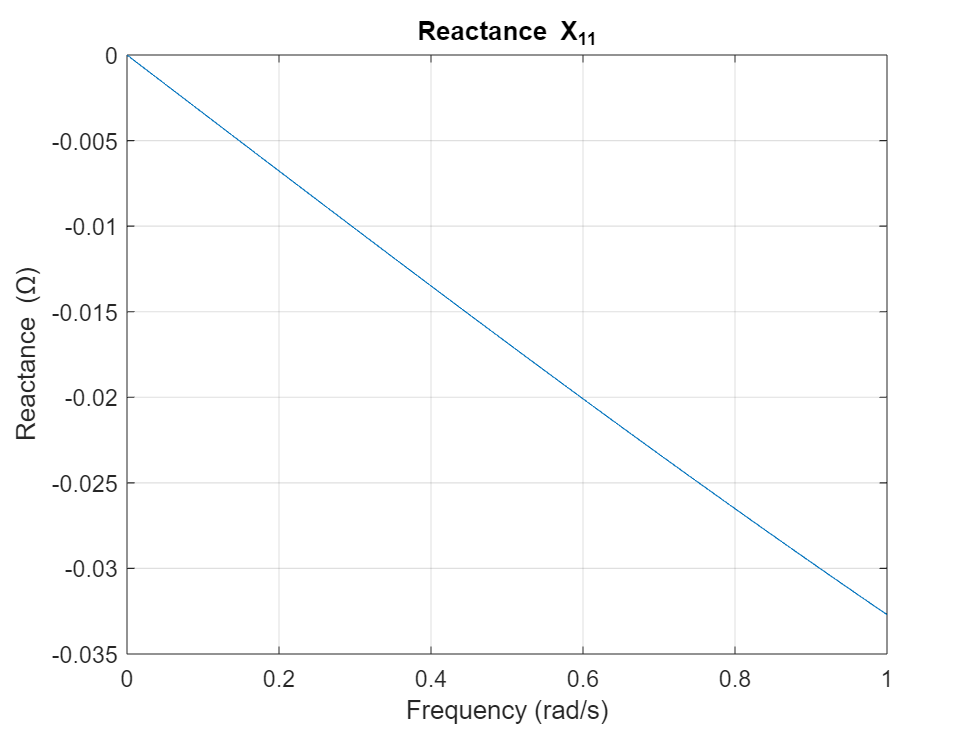

s = tf('s');
freqs = linspace(0, 1, 500);

Z = zpk(-10, [-5.6+1.6j, -5.6-1.6j], 0.5);
F = frd(Z, freqs, 'FrequencyUnit', 'rad/s');
plot(freqs, imag(F.ResponseData(:))); title('Reactance X_1_1'); xlabel('Frequency (rad/s)'); ylabel('Reactance (\Omega)'); grid on;

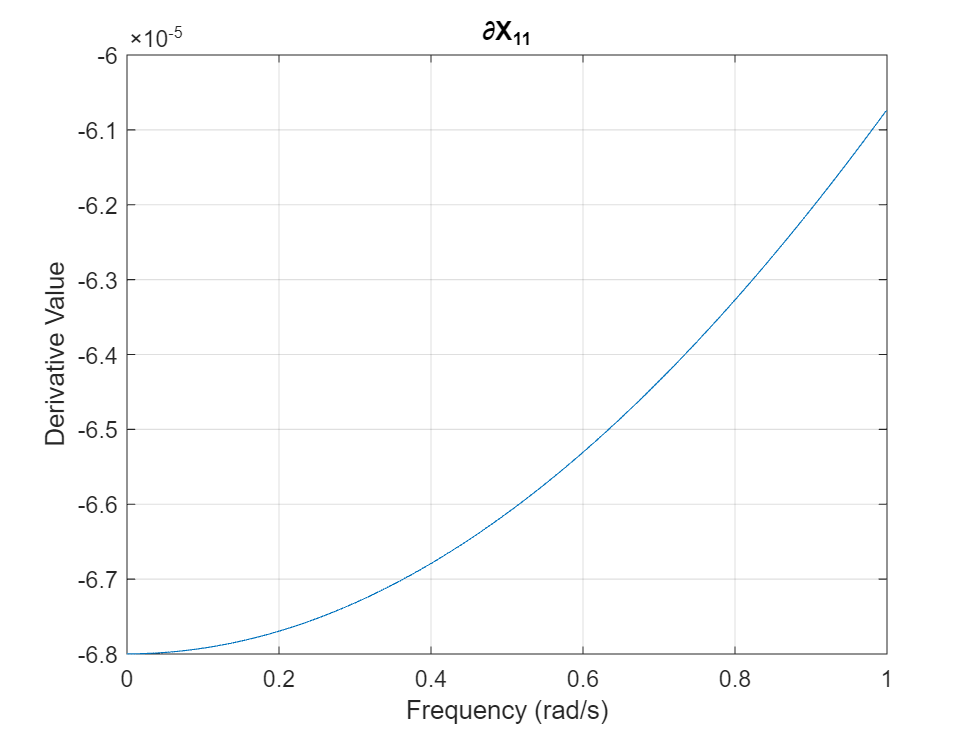

plot(freqs, gradient(imag(F.ResponseData(:)))); title('\partialX_1_1'); xlabel('Frequency (rad/s)'); ylabel('Derivative Value'); grid on;

Q = [1, -0.95; -0.95, 0];
H = [Z; 1];
getSectorIndex(H, Q)

ans = 1.0000